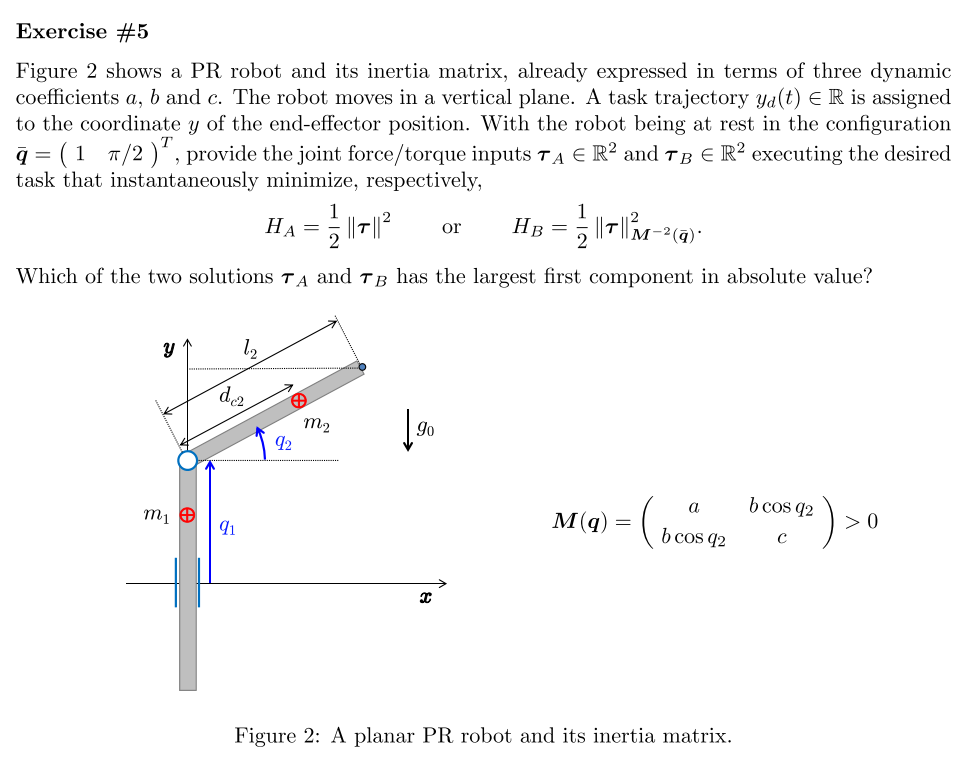 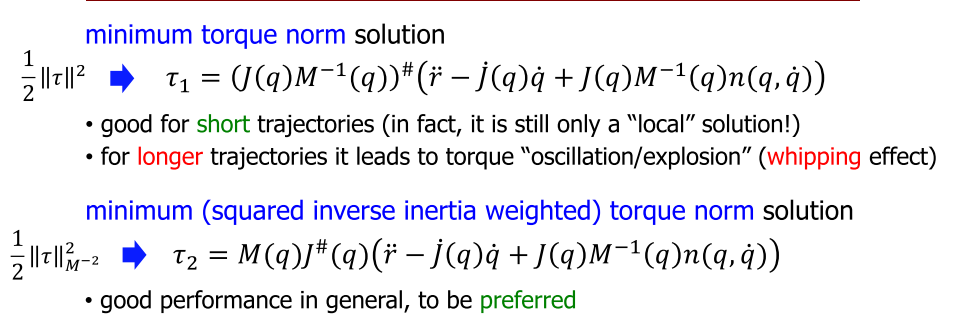

clc
clear all
close all

syms q1 q2 l2 a b c y_d y_dot_d y_dot_dot_d g0 m1 m2 d_c2 d_c1 g1 g2 real
g=[0 -g0]'

$$g = \left(\begin{array}{c} 0\\ -g_{0} \end{array}\right)$$

q=[q1 q2]';

y=[q1+sin(q2)*l2];
J=jacobian(y,q);

q_bar=[1 pi/2]';

M=[a          b*cos(q2); 
   b*cos(q2)  c         ];

U=-m1*g0*(q1-d_c1)-m2*g0*(q1+d_c2*sin(q2));
g=jacobian(U,q)'; %n=g
g_sym=[g1 g2]';
M_inv=inv(M);

tau_a=pinv(J*M_inv)*(y_dot_dot_d+J*M_inv*g_sym);
simplify(pinv(J*M_inv));

tau_a_bar=subs(tau_a, q, q_bar);

simplify(M*M');

tau_b=M*pinv(J)*(y_dot_dot_d+J*M_inv*g_sym);

simplify(M*pinv(J));

tau_b_bar=subs(tau_b, q, q_bar);
g=[0 -g0]';
rc1=[0 q1-d_c1]';
rc2=[d_c2*cos(q2) q1+d_c2*sin(q2)]';
U6=-m1*g'*rc1-m2*g'*rc2;
g_fun=hessian(U6, q)

$$g\_fun = \left(\begin{array}{cc} 0 & 0\\ 0 & -d_{\mathrm{c2}}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$


eig(g_fun)

$$ans = \left(\begin{array}{c} 0\\ -d_{\mathrm{c2}}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$